# ENG432 Major Design Project

Samuel Brown 619710

Paramaters

clc; close all; clear all;

% F-16 Dynamics
% Long          % Lat
Xu = -0.0016;   Yb = -27.38;
Xw = 0.0103;    Lb = -28.08;
Zu = -0.1179;   Nb = 5.481;
Zw = -0.3907;   Yp = 0.389;
dMw = 0.0023;   Yr = 0.538;
Mu = 0.0085;    Lp = -1.644;
Mw = 0.0049;    Lr = 0.333;
Mq = -0.500;    Np = -0.081;
Zse = 23.5329;  Nr = -1.504;
Mse = -12.7322; Ysr = 4.588;
Xse = 3.651;    Lsr = 9.591;
Xst = 4.2711;   Lsa = 47.92;
                Nsr = -1.908;
                Nsa = -1.429;
% Vars
v0 = 182;                
m_ref = 0.6;                
m = 9295;
i_x = 12875;
i_y = 75674;
i_z = 85552;                
i_xz = 1331;               
p_den = 0.460;
s_area = 27.871;
b_span = 9.144;
c_chord = 3.45;

% Calc Vars
M = m/(.5*p_den*v0*s_area);
I_x = i_x/(.5*p_den*v0*s_area*b_span);
I_y = i_y/(.5*p_den*v0*s_area*c_chord);
I_z = i_z/(.5*p_den*v0*s_area*b_span);
I_xz = i_xz/(.5*p_den*v0*s_area*b_span);

% dXw, dZw, Xq, Zq, Mst, Zst, Ysa = 0
% [v n τ 𝜉 𝜁 ] => [b se st sa sr]
te = 5*pi/180; We = v0*sin(te); Ue = v0*cos(te); g = 9.81;

% Long Concise Dervivative
xu = Xu/M;
zu = Zu/M;
mu = (Mu/I_y)+(c_chord*dMw*Zu/(v0*I_y*M));
xw = Xw/M;
zw = Zw/M;
mw = (Mw/I_y)+(c_chord*dMw*Zw/(v0*I_y*M));
xq = -We;
zq = Ue;
mq = (c_chord*Mq/I_y)+(Ue*c_chord*dMw/(I_y*v0));
xt = -g*cos(te);
zt = -g*sin(te);
mt = -c_chord*dMw*g*sin(te)/I_y;

xse = v0*Xse/M;
zse = v0*Zse/M;
mse = (v0*Mse/I_y)+(c_chord*dMw*Zse/(I_y*M));
xst = v0*Xst/M;
zst = 0;
mst = 0;

% Lat Concise Derivative
% given beta = y velocity / eqilbrium velocity, 
% the beta data was normalised with the y velocity formula   
yb = Yb/M;
yp = (b_span*Yp+M*We)/M;
yr = (b_span*Yr-M*Ue)/M;
yphi = g*cos(te);
lb = (I_z*Lb+I_xz*Nb)/(I_x*I_z-I_xz^2);
lp = (I_z*Lp+I_xz*Np)/(I_x*I_z-I_xz^2);
lr = (I_z*Lr+I_xz*Nr)/(I_x*I_z-I_xz^2);
lphi = 0;
nb = (I_x*Nb+I_xz*Lb)/(I_x*I_z-I_xz^2);
np = (I_x*Np+I_xz*Lp)/(I_x*I_z-I_xz^2);
nr = (I_x*Nr+I_xz*Lr)/(I_x*I_z-I_xz^2);
nphi = 0;

ysa = 0;
lsa = v0*(I_z*Lsa+I_xz*Nsa)/(I_x*I_z-I_xz^2);
nsa = v0*(I_x*Nsa+I_xz*Lsa)/(I_x*I_z-I_xz^2);
ysr = v0*Ysr/M;
lsr = v0*(I_z*Lsr+I_xz*Lsr)/(I_x*I_z-I_xz^2); 
nsr = v0*(I_x*Nsr+I_xz*Lsr)/(I_x*I_z-I_xz^2); % Error in handout use v0*(I_x not v0*(I_z

% Dim
% [v n τ 𝜉 𝜁 ] => [b se st sa sr]
Xu = -0.0016*.5*p_den*v0*s_area;                Yb = -27.38*.5*p_den*v0*s_area;
Xw = 0.0103*.5*p_den*v0*s_area;                 Lb = -28.08*.5*p_den*v0*s_area*b_span;
Zu = -0.1179*.5*p_den*v0*s_area;                Nb = 5.481*.5*p_den*v0*s_area*b_span;
Zw = -0.3907*.5*p_den*v0*s_area;                Yp = 0.389*.5*p_den*v0*s_area*b_span;
dMw = 0.0023*.5*p_den*s_area*c_chord^2;         Yr = 0.538*.5*p_den*v0*s_area*b_span;
Mu = 0.0085*.5*p_den*v0*s_area*c_chord;         Lp = -1.644*.5*p_den*v0*s_area*b_span^2;
Mw = 0.0049*.5*p_den*v0*s_area*c_chord;         Lr = 0.333*.5*p_den*v0*s_area*b_span^2;
Mq = -0.500*.5*p_den*v0*s_area*c_chord^2;       Np = -0.081*.5*p_den*v0*s_area*b_span^2;
Zse = 23.5329*.5*p_den*v0^2*s_area;             Nr = -1.504*.5*p_den*v0*s_area*b_span^2;
Mse = -12.7322*.5*p_den*v0^2*s_area*c_chord;    Ysr = 4.588*.5*p_den*v0^2*s_area;
Xse = 3.651*.5*p_den*v0^2*s_area;               Lsr = 9.591*.5*p_den*v0^2*s_area*b_span;
Xst = 4.2711;                                   Lsa = 47.92*.5*p_den*v0^2*s_area*b_span;
                                                Nsr = -1.908*.5*p_den*v0^2*s_area*b_span;
                                                Nsa = -1.429*.5*p_den*v0^2*s_area*b_span;

% Dim long
dxu = Xu/m;
dzu = Zu/m;
dmu = (Mu/i_y)+(dMw*Zu/(i_y*m));
dxw = Xw/m;
dzw = Zw/m;
dmw = (Mw/i_y)+(dMw*Zw/(i_y*m));
dxq = -We;
dzq = Ue;
dmq = (Mq/i_y)+(Ue*dMw/(i_y));
dxt = -g*cos(te);
dzt = -g*sin(te);
dmt = -dMw*g*sin(te)/i_y;

dxse = Xse/m;
dzse = Zse/m;
dmse = (Mse/i_y)+(dMw*Zse/(i_y*m));
dxst = Xst/m;
dzst = 0;
dmst = 0;

%Dim lat
dyb = Yb/m;
dyp = (Yp+m*We)/m;
dyr = (Yr-m*Ue)/m;
dyphi = g*cos(te);
dlb = (i_z*Lb+i_xz*Nb)/(i_x*i_z-i_xz^2);
dlp = (i_z*Lp+i_xz*Np)/(i_x*i_z-i_xz^2);
dlr = (i_z*Lr+i_xz*Nr)/(i_x*i_z-i_xz^2);
dlphi = 0;
dnb = (i_x*Nb+i_xz*Lb)/(i_x*i_z-i_xz^2);
dnp = (i_x*Np+i_xz*Lp)/(i_x*i_z-i_xz^2);
dnr = (i_x*Nr+i_xz*Lr)/(i_x*i_z-i_xz^2);
dnphi = 0;

dysa = 0;
dlsa = (i_z*Lsa+i_xz*Nsa)/(i_x*i_z-i_xz^2);
dnsa = (i_x*Nsa+i_xz*Lsa)/(i_x*i_z-i_xz^2);
dysr = Ysr/m;
dlsr = (i_z*Lsr+i_xz*Lsr)/(i_x*i_z-i_xz^2); 
dnsr = (i_x*Nsr+i_xz*Lsr)/(i_x*i_z-i_xz^2);

% Long
x1 = {'u' 'w' 'q' 'theta'};
a1 = [xu xw xq xt; zu zw zq zt; mu mw mq mt; 0 0 1 0];

b1 = [xse xst; zse zst; mse mst; 0 0];
c1 = [0 1 0 0; 0 0 1 0];
u1 = {'se' 'st'};
y1 = {'z velocity' 'pitch rate'};

c12 = [1 0 0 0; 0 0 0 1];
y12 = {'x velocity' 'pitch angle'};

% Lat
x2 = {'beta' 'p' 'r' 'phi'};
a2 = [yb yp yr yphi; lb lp lr lphi; nb np nr nphi; 0 1 0 0];

b2 = [ysa ysr; lsa lsr; nsa nsr; 0 0];
c2 = [0 0 0 1; 0 0 1 0];
u2 = {'sa' 'sr'};
y2 = {'bank angle' 'yaw rate'};

c22 = [1 0 0 0; 0 1 0 0];
y22 = {'sideslip angle' 'roll rate'};

% Dim
% Long
da1 = [dxu dxw dxq dxt; dzu dzw dzq dzt; dmu dmw dmq dmt; 0 0 1 0];
db1 = [dxse dxst; dzse dzst; dmse dmst; 0 0];

% Lat
da2 = [dyb dyp dyr dyphi; dlb dlp dlr dlphi; dnb dnp dnr dnphi; 0 1 0 0];
db2 = [dysa dysr; dlsa dlsr; dnsa dnsr; 0 0]; 



Question 2) Open loop step response

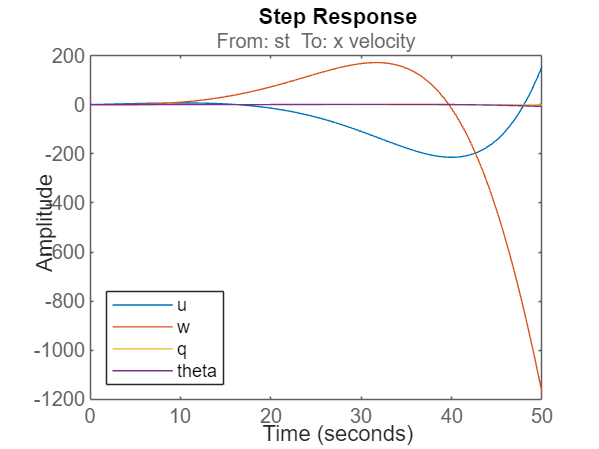

st = 0.01;       %A) (1% Thrust)
se = 0.0174533;  %B)  rad (1deg increase in Elevator positon)
sa = 0.0174533;  %C)  rad (1deg increase in Aileron position)
sr = 0.0174533;  %D)  rad (1deg increase in Rudder position)

sys_mimo11 = ss(a1,b1,c1,0,'statename',x1,...
'inputname',u1,...
'outputname',y1);

sys_mimo21 = ss(a2,b2,c2,0,'statename',x2,...
'inputname',u2,...
'outputname',y2);

sys_mimo12 = ss(a1,b1,c12,0,'statename',x1,...
'inputname',u1,...
'outputname',y12);

sys_mimo22 = ss(a2,b2,c22,0,'statename',x2,...
'inputname',u2,...
'outputname',y22);

stSysW = sys_mimo11(1,2);
seSysW = sys_mimo11(1,1);
saSysR = sys_mimo21(1,1);
srSysR = sys_mimo21(1,2);
stSysQ = sys_mimo11(2,2);
seSysQ = sys_mimo11(2,1);
saSysPhi = sys_mimo21(2,1);
srSysPhi = sys_mimo21(2,2);

stSysU = sys_mimo12(1,2);
seSysU = sys_mimo12(1,1);
saSysB = sys_mimo22(1,1);
srSysB = sys_mimo22(1,2);
stSysTheta = sys_mimo12(2,2);
seSysTheta = sys_mimo12(2,1);
saSysP = sys_mimo22(2,1);
srSysP = sys_mimo22(2,2);

optSe = RespConfig;
optSe.Amplitude = se;

optSa = RespConfig;
optSa.Amplitude = sa;

optSt = RespConfig;
optSt.Amplitude = st;

optSr = RespConfig;
optSr.Amplitude = sr;

t1 = 0:0.05:50;
t2 = 0:0.05:50;

%Long sys
figure; grid on; hold on;
step(stSysU,t1, optSt)
step(stSysW,t1, optSt)
step(stSysQ,t1, optSt)
step(stSysTheta,t1, optSt)
legend(x1,Location="southwest"); hold off;

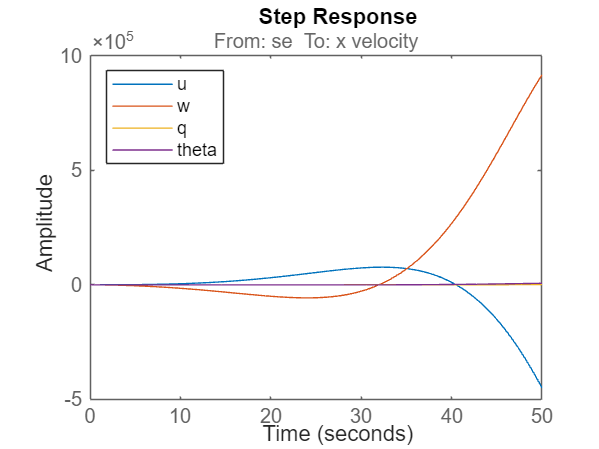


figure; hold on;
step(seSysU,t1, optSe)
step(seSysW,t1, optSe)
step(seSysQ,t1, optSe)
step(seSysTheta,t1, optSe)
legend(x1,Location="northwest"); hold off;

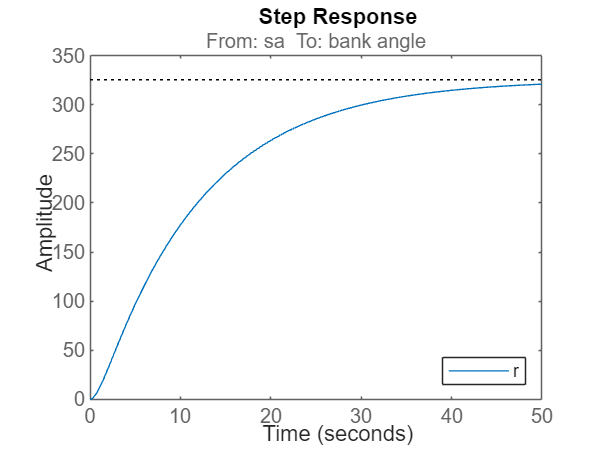


%Lat sys
x2r = {'beta' 'p' 'phi'};
figure; hold on;
step(saSysR,t2, optSa)
legend('r',Location="southeast"); hold off;

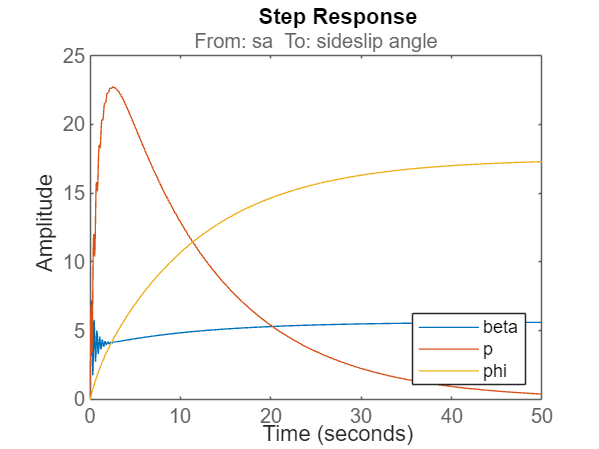


figure; hold on;
step(saSysB,t2, optSa)
step(saSysP,t2, optSa)
step(saSysPhi,t2, optSa)
legend(x2r,Location="southeast"); hold off;

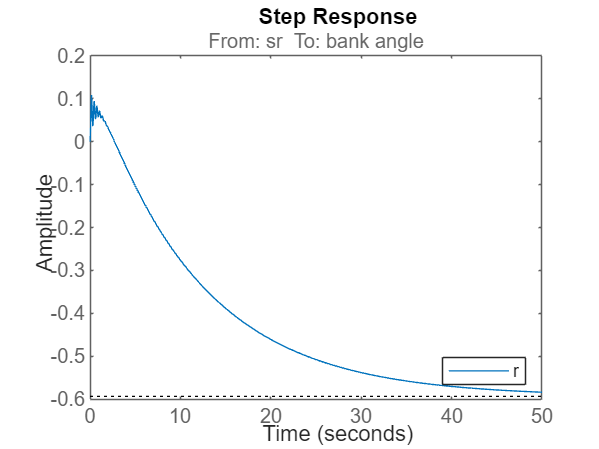


figure; hold on;
step(srSysR,t2, optSr)
legend('r',Location="southeast"); hold off;

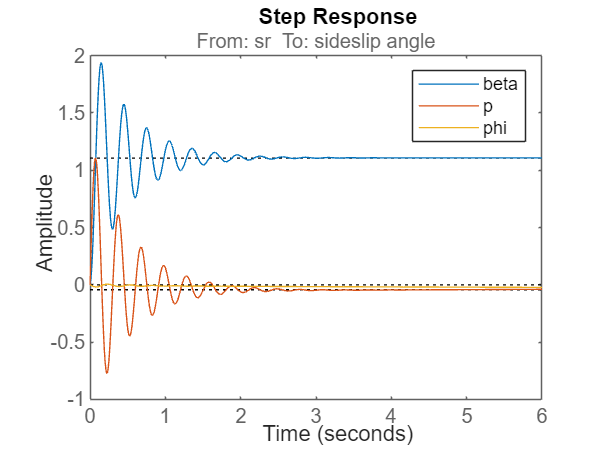


t2 = 0:0.01:6;
figure; hold on;
step(srSysB,t2, optSr)
step(srSysP,t2, optSr)
step(srSysPhi,t2, optSr)
legend(x2r,Location="northeast"); hold off;

Question 3) Controllability and Observability

co1 = ctrb(a1,b1);
unCo1 = length(a1) - rank(co1)

unCo1 = 0


co2 = ctrb(a2,b2);
unCo2 = length(a2) - rank(co2)

unCo2 = 0


b = zeros(4,2);
unCoA = zeros(4,2);
unCoB = zeros(4,2);

for k = 1:2
    for j = 1:4
        b = zeros(4,2);
        b(j,k) = 1;

        coA = ctrb(a1,b);
        unCoA(j,k) = length(a1)-rank(coA);
        coB = ctrb(a2,b);
        unCoB(j,k) = length(a2)-rank(coB);

    end
end

unCoA

unCoA =      0     0
     0     0
     0     0
     0     0


unCoB

unCoB =      0     0
     0     0
     0     0
     0     0



c = zeros(2,4);
unOb1 = zeros(2,4);
unOb2 = zeros(2,4);

for k = 1:4
    for j = 1:2
        c = zeros(2,4);
        c(j,k) = 1;

        ob1 = obsv(a1,c);
        unOb1(j,k) = length(a1)-rank(ob1);
        ob2 = obsv(a2,c);
        unOb2(j,k) = length(a2)-rank(ob2);

    end
end

unOb1

unOb1 =      0     0     0     0
     0     0     0     0


unOb2

unOb2 =      0     0     0     0
     0     0     0     0


Question 4) Major Minor Loop Design

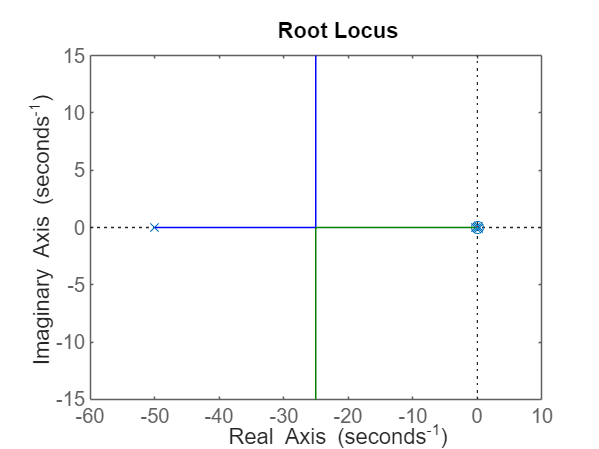

s = tf('s');

t = .02;
b = 1/t;
delay = b / (s + b);

pl = tf(ss(a1, b1, [0 0 1 0], 0));
pl = pl(1);

Gmin = pl*delay;

K2 = -.7;
GminL = K2 * Gmin;
rlocus(GminL)

TminL = feedback(GminL, 1);
Tmin = minreal(zpk(TminL), 2e-3);
[ppS, zzS] = pzmap(Tmin)

ppS =   -0.0468 + 0.0000i
 -25.0466 +60.7546i
 -25.0466 -60.7546i
  -0.0003 + 0.0067i
  -0.0003 - 0.0067i


zzS =    -0.0475
   -0.0003
    0.0000


[WnS, zetaS, pS] = damp(Tmin);

wnS = WnS(end);
zS = zetaS(end);

zP = .04;
wnP = wnS/10;

sP = zP*wnP 

sP = 0.2629

wdP = wnP*sqrt(1-zP^2)

wdP = 6.5662

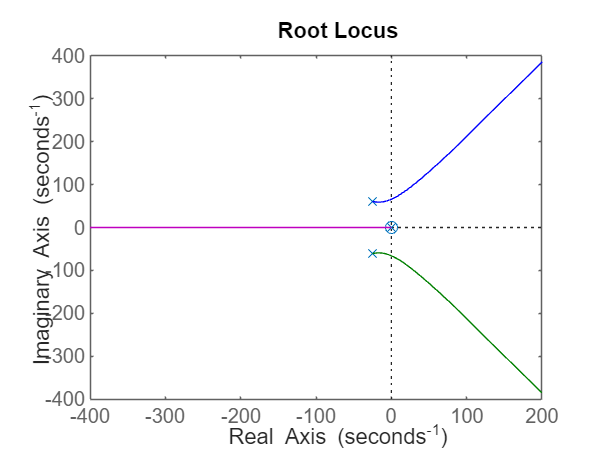


K1 = 6.2;
Gmaj = K1 * Tmin / s;
rlocus(Gmaj)

TmajL = feedback(Gmaj, 1);
Tmaj = minreal(zpk(TmajL), 1e-3);
[ppP, zzP] = pzmap(Tmaj)

ppP =   -6.6361 + 0.0000i
  -0.0003 + 0.0000i
 -21.7283 +59.6483i
 -21.7283 -59.6483i


zzP = -2.9069e-04

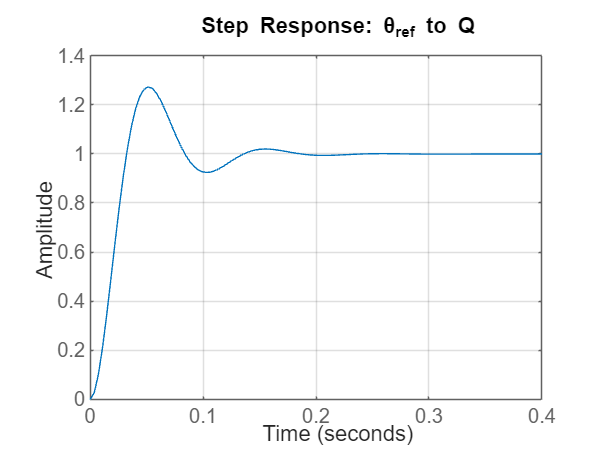

[WnP, zetaP, pP] = damp(Tmaj);

figure;
step(Tmin, .4);
title('Step Response: θ_{ref} to Q');
grid on;

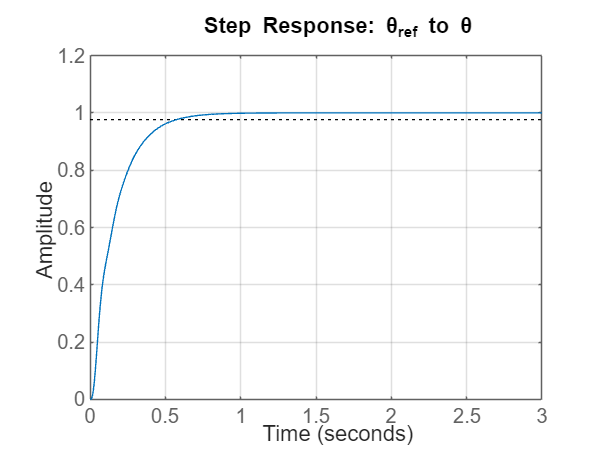


figure;
step(Tmaj, 3);
title('Step Response: θ_{ref} to θ');
grid on;


gain4 = dcgain(Tmaj)

gain4 = 0.9764

Question 5) LQR Regulator

Question 6) Controller Pole Placement

% Define reference values
Href = 60;  % From 9144m + Href
Mref = 0.6*343 - 182;         % Mach number

% Augment the system to include height h and mach number m
x6 = {'u', 'w', 'q', 'theta', 'h'};
y6 = {'mach number', 'height'};

A_a = zeros(5,5);
A_a(1:4,1:4) = a1;
A_a(5,1:4) = [0, 1, 0, 0]; % dh/dt = y velocity
B_a = [b1; [0 0]]; % Approximation
C_a = [1 0 0 0 0; 0 0 0 1 0];

sys_mimo6 = ss(A_a,B_a,C_a,zeros(2,2),'statename',x6,...
'inputname',u1,...
'outputname',y6);

rank(ctrb(sys_mimo6))

ans = 5

rank(obsv(sys_mimo6))

ans = 4

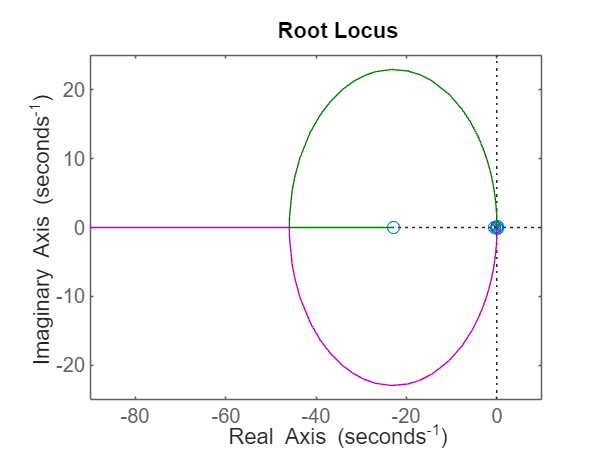


% Original system
A = A_a;
B = B_a;
C = C_a;

% Augment with integrators
n = size(A,1);    % Number of states
p = size(C,1);    % Number of outputs

A_aug = [A, zeros(n,p); -C, zeros(p)];
B_aug = [B; zeros(p, size(B,2))];
C_aug = [C, zeros(p,p)];
Co = ctrb(A_aug, B_aug);

[Ac,Bc,Cc,T,k] = ctrbf(A_aug,B_aug,C_aug);

% Extract controllable subsystem
A_c = Ac(2:7, 2:7);
B_c = Bc(2:7, :);

% Place augmented poles
wn = 4;
%Eig_aug = roots([1, 3.5*wn, 7*wn^2, 9*wn^3, 7*wn^4, 4*wn^5, 2*wn^6, wn^7]);
Eig_aug = roots([1, 3.25*wn, 6.6*wn^2, 8.6*wn^3, 7.45*wn^4, 3.95*wn^5, wn^6]);
K_c = place(A_c, B_c, Eig_aug);

K_aug_c = [K_c, zeros(2,1)];
K_aug = K_aug_c * T^-1;

Kx = K_aug(:,1:n);   % Feedback gain for original states
Ki = -K_aug(:,n+1:end); % Integral gain

A_pl = [A_a - B_a*Kx, B_a*Ki; 
        -C, zeros(p)];
B_pl = [zeros(n,p); eye(p)];
C_pl = [C_a, zeros(p)];
D_pl = zeros(p);

sys_pl = ss(A_pl, B_pl, C_pl, D_pl);

s = tf('s');

Cont1 = 8e-7*(s^2 - 0.1923*s + 0.01977)*(s+.03)/(s*0.0198*(s+0.04951));
Cont2 = 1e-8*(s^2 - 0.1923*s + 0.01977)*(s+1)/(s*(s+.02)*0.0198) * (s+1)/(s+.004);

% Input 1 lag: .2 / (s+.2)
GC1 = ss(Cont1);

% Input 2 lag: 50 / (s+50)
GC2 = ss(Cont2);

% Combine into diagonal (MIMO) system
control_block = blkdiag(GC1, GC2);

% Lag Times
tMM = .05;
tTS = 5;
tES = .02;
tA = .8;

% Input 1 lag: .2 / (s+.2)
A1 = -1/tTS; B1 = 1; C1 = 1/tTS; D1 = 0;
G1 = ss(A1, B1, C1, D1);

% Input 2 lag: 50 / (s+50)
A2 = -1/tES; B2 = 1; C2 = 1/tES; D2 = 0;
G2 = ss(A2, B2, C2, D2);

% Combine into diagonal (MIMO) system
G1.StateName = {'lag_mach'};
G2.StateName = {'lag_height'};
lag_block = blkdiag(G1, G2);

sys_control_forward = series(control_block, lag_block);
sys_forward = series(sys_control_forward, sys_mimo6);
%sys_forward = series(lag_block, sys_pl);

rlocus(sys_forward(1,1))

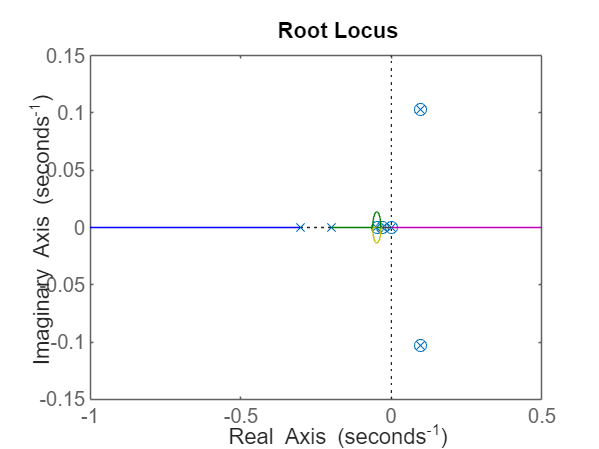

rlocus(sys_forward(2,1))

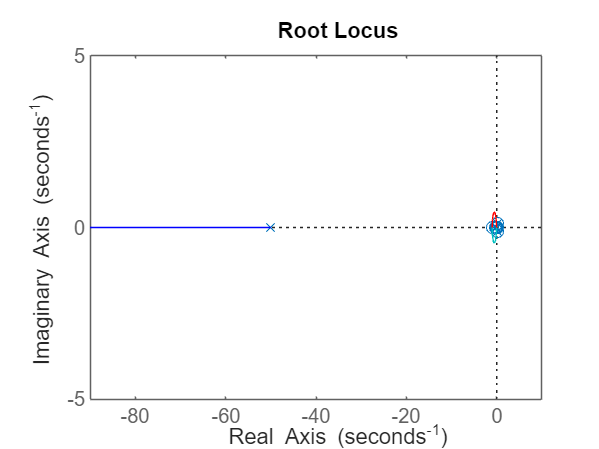

rlocus(sys_forward(1,2))

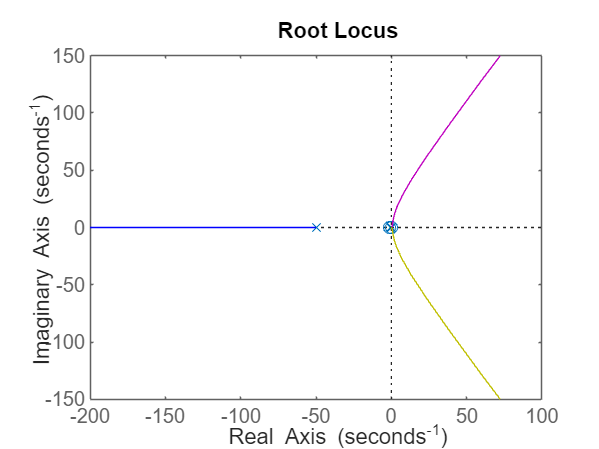

rlocus(sys_forward(2,2))


% Feedback lag 1: H(s) = 20 / (s + 20)
A_f1 = -1/tMM; B_f1 = 1; C_f1 = 1/tMM; D_f1 = 0;
H1= ss(A_f1, B_f1, C_f1, D_f1);  

% Feedback lag 2: H(s) = 1.25 / (s + 1.25)
A_f2 = -1/tA; B_f2 = 1; C_f2 = 1/tA; D_f2 = 0;
H2= ss(A_f2, B_f2, C_f2, D_f2);  

H1.StateName = {'y_mach'};
H2.StateName = {'y_height'};
H_mimo = blkdiag(H1, H2);  % 2x2 MIMO if there are two outputs fed back

sys_cl = feedback(sys_forward, H_mimo);  % Negative feedback: u = r - H(s)*y
sys_cl.InputName = {'Mref', 'Href'};

tol = 1e-3;

output = zpk(minreal(zpk(tf(sys_cl)),tol))

output =
 
  From input "Mref" to output...
                   0.00067397 (s+22.93) (s+0.6111)
   mach number:  ------------------------------------
                 (s+0.3657) (s^2 + 0.1371s + 0.02582)
 
                            -0.00099598 s (s+0.04751) (s+0.02) (s+0.004) (s+0.0002907)
   height:  ------------------------------------------------------------------------------------------
            (s+0.3657) (s+0.04951) (s+0.02034) (s^2 + 0.003643s + 4.883e-06) (s^2 + 0.1371s + 0.02582)
 
  From input "Href" to output...
                                  0.0024639 s (s+1)^2 (s+0.2896) (s+0.2) (s-0.1435) (s-0.005787)
   mach number:  -------------------------------------------------------------------------------------------------
                 (s+50) (s+0.3657) (s+0.03002) (s+0.02034) (s^2 + 0.003643s + 4.883e-06) (s^2 + 0.1371s + 0.02582)
 
                               1.1139e-06 (s+64.34) (s+1)^2 (s+0.04783) (s+0.02892) (s^2 - 0.0648s + 0.01406)
   height:  ----------------

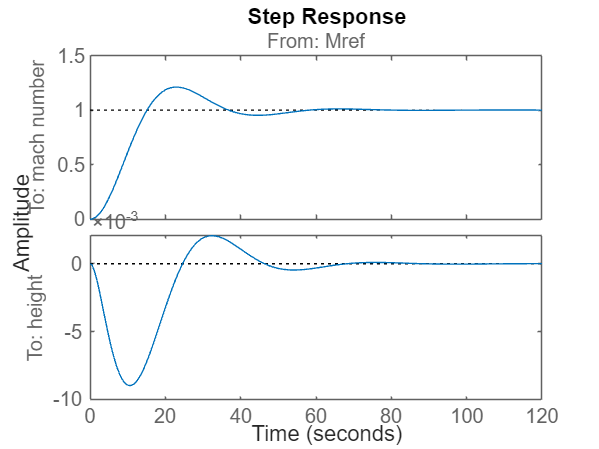

step(output(:,1))

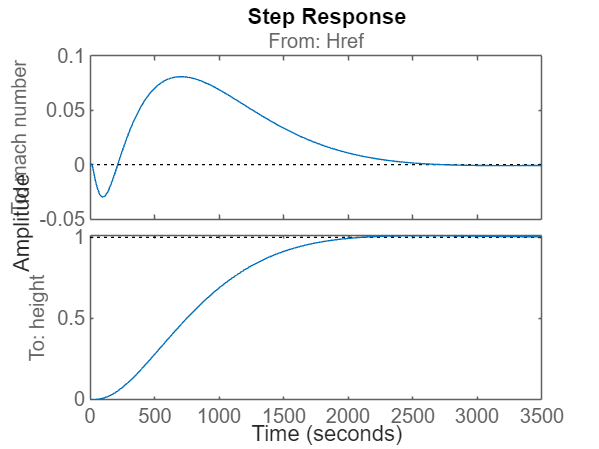

step(output(:,2))

dcgain(zpk(minreal(zpk(tf(sys_cl)),tol)))

ans =     1.0003    0.0000
    0.0000    1.0002


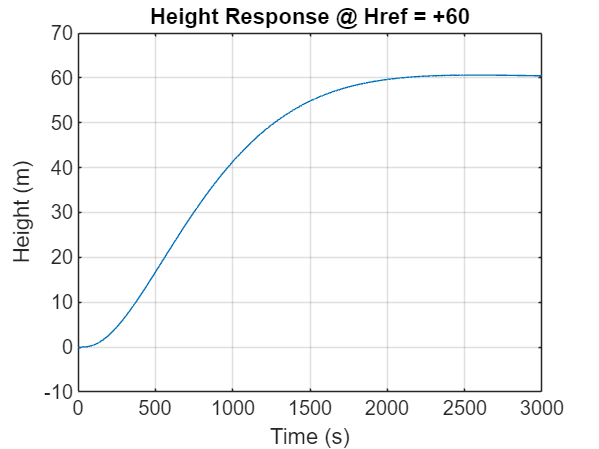


optH = RespConfig;
optH.Amplitude = Href;

optM = RespConfig;
optM.Amplitude = Mref;


% Create RespConfig objects for step amplitudes
optM = RespConfig;
optM.Amplitude = Mref;  % Step amplitude for Mach number reference

optH = RespConfig;
optH.Amplitude = Href;  % Step amplitude for height reference
t1 = 0:0.1:120;
t2 = 0:0.1:3e3;

figure;
plot(t2, step(output(2,2), t2, optH)+ step(output(2,1), t2, optM))
title('Height Response @ Href = +60')
ylabel('Height (m)');
xlabel('Time (s)'); grid on;

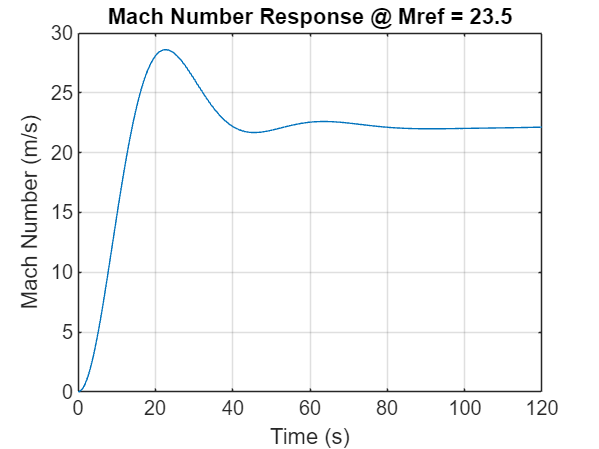


figure;
plot(t1, step(output(1,1), t1, optM)+ step(output(1,2), t1, optH))
title('Mach Number Response @ Mref = 23.5')
ylabel('Mach Number (m/s)');
xlabel('Time (s)'); grid on;

Question 7) Model Perdictive Control

K =     2.6015   -3.5083  -18.3891  486.3492   -1.0000


S = 1.0e+08 *

    0.0000   -0.0000   -0.0000    0.0005    0.0000
   -0.0000    0.0000    0.0002   -0.0075    0.0000
   -0.0000    0.0002    0.0008   -0.0323    0.0000
    0.0005   -0.0075   -0.0323    1.3615   -0.0004
    0.0000    0.0000    0.0000   -0.0004    0.0000


P = 1.0e+02 *

  -0.0000 + 0.0003i
  -0.0000 - 0.0003i
  -0.0100 + 0.0000i
  -0.4022 + 0.0000i
  -5.5635 + 0.0000i


ans = 1.0e+02 *

  -5.5635 + 0.0000i
  -0.4022 + 0.0000i
  -0.0100 + 0.0000i
  -0.0000 + 0.0003i
  -0.0000 - 0.0003i


ans =    1.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0179 + 0.0000i
   0.9050 + 0.0000i
   0.9998 + 0.0026i
   0.9998 - 0.0026i
   0.0067 + 0.0000i


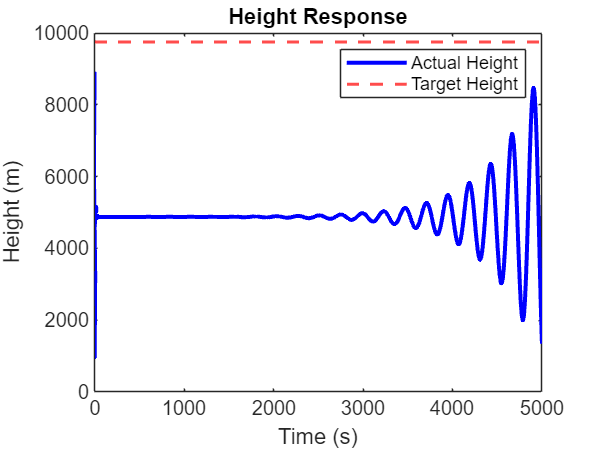

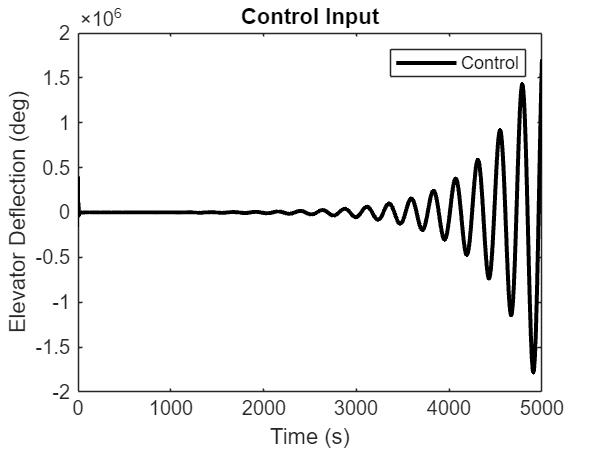

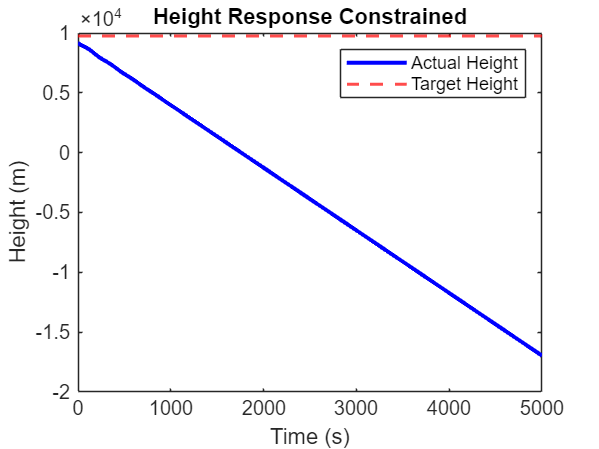

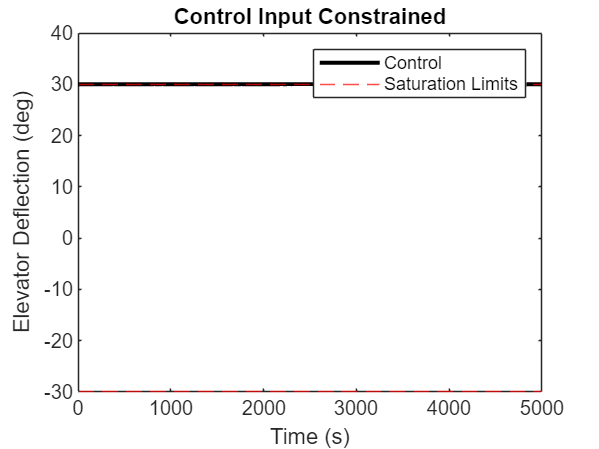

s = tf('s');

% Setup
Hs = 0.3048 * 30000; % Initial height (m)
Href = 0.3048 * 32000; % Reference height (m)
delayA = 0.8; % actuator delay (s)

% Time constants
b = 1 / 0.02;
delayE = b / (s + b);
DelayE_block = ss(delayE); % first-order low-pass delay

% System definition (example a1, b1)
% Replace with your actual a1, b1 matrices
a1 = rand(4); % Example 4x4 dynamics
b1 = rand(4,1); % Example 4x1 input matrix

% Augment system with height state
A_aug = zeros(5,5);
A_aug(1:4,1:4) = a1;
A_aug(5,2) = 1; % integrate second state for height

B_aug = [b1(:,1); 0];
C_aug = [0 0 0 0 1]; % output is height

sys_aug = ss(A_aug, B_aug, C_aug, 0);

% LQR Design
Q = diag([1 1 1 1 1]);
R_lqr = 1;
[K,~,~] = lqr(sys_aug, Q, R_lqr);

% Build closed-loop system
sys_cl = ss(A_aug - B_aug*K, B_aug, C_aug, 0);

% Combine with delay block
sys_forward = series(DelayE_block, sys_cl);

% Discretize the forward system
ts = 0.1;
sysd = c2d(sys_forward, ts, 'zoh');

% Extract state-space matrices
a = sysd.A;
b = sysd.B;
c = sysd.C;

% Augment for reference tracking
A = [a zeros(size(a,1),1); c*a 1];
B = [b; c*b];
C = [zeros(1,size(a,2)) 1];

% MPC Parameters
np = 50; % prediction horizon
nc = 3;  % control horizon
R = 1;

% MPC matrices
F = C*A;
for k = 2:np
    F = [F; C*A^k];
end

Th = zeros(np,nc);
for j = 1:np
    for k = 1:nc
        if j >= k
            Th(j,k) = C*A^(j-k)*B;
        end
    end
end

% Constraints
M = [[-1; 1], zeros(2,nc-1)];
Gamma = [deg2rad(-30); deg2rad(30)];

% Simulation setup
Nsim = round(500 / ts);
dK = round(delayA / ts);

% Initial conditions
xk = zeros(size(A,1),1);
xk(end) = Hs; 
xkc = xk;

xref = Href;

% Data storage
height_log = ones(Nsim+dK,1)*Hs;
control_log = zeros(Nsim+dK,1);
height_logc = ones(Nsim+dK,1)*Hs;
control_logc = zeros(Nsim+dK,1);
time = (1:Nsim)*ts;

% Simulation loop
for k = dK+1:Nsim+dK
    % Reference signals
    Rs = (xref - height_log(k-dK)) * ones(np,1);
    Rsc = (xref - height_logc(k-dK)) * ones(np,1);

    % Cost function
    F0  = 2*Th'*F*xk - 2*Th'*Rs;
    F0c = 2*Th'*F*xkc - 2*Th'*Rsc;
    E0  = 2*(Th'*Th + R*eye(nc));
    invE0 = inv(E0);

    % Constrained control via Hildreth
    P0c = M * invE0 * M';
    K0c = Gamma + M * invE0 * F0c;

    lc = zeros(2,1);
    for m = 1:7
        lc(1) = max(-(K0c(1) + P0c(1,2)*lc(2)) / P0c(1,1), 0);
        lc(2) = max(-(K0c(2) + P0c(2,1)*lc(1)) / P0c(2,2), 0);
    end

    UoptC = -invE0*F0c - invE0*M'*lc;
    Uopt  = -invE0*F0;

    Uk = Uopt(1);
    Ukc = UoptC(1);

    % State updates
    xk = A*xk + B*Uk;
    xkc = A*xkc + B*Ukc;

    % Log
    height_log(k) = xk(end);
    control_log(k) = rad2deg(Uk);

    height_logc(k) = xkc(end);
    control_logc(k) = rad2deg(Ukc);
end

% Trim initial delay offset
height_log = height_log(dK+1:end);
control_log = control_log(dK+1:end);
height_logc = height_logc(dK+1:end);
control_logc = control_logc(dK+1:end);

% Plot: Unconstrained
figure;
plot(time, height_log, 'b', 'LineWidth', 2); hold on;
yline(Href, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Height (m)');
title('Height Response - Unconstrained');
legend('Actual Height','Target Height');

figure;
plot(time, control_log, 'k', 'LineWidth', 2); hold on;
xlabel('Time (s)'); ylabel('Elevator Deflection (deg)');
title('Control Input - Unconstrained');

% Plot: Constrained
figure;
plot(time, height_logc, 'b', 'LineWidth', 2); hold on;
yline(Href, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)'); ylabel('Height (m)');
title('Height Response - Constrained');
legend('Actual Height','Target Height');

figure;
plot(time, control_logc, 'k', 'LineWidth', 2); hold on;
yline(30, 'r--'); yline(-30, 'r--');
xlabel('Time (s)'); ylabel('Elevator Deflection (deg)');
title('Control Input - Constrained');
legend('Control','Saturation Limits');